# Graph Classification using GCN

v0.5

TL;DR : **Graph Classification proof-of-concept example**

This simple example demonstrates a custom implementation of GCN (graph Convolution network) for graph level classification task. We have used PROTEINS dataset here (or rather a subset of it)

Dataset ref: https://ls11-www.cs.tu-dortmund.de/staff/morris/graphkerneldatasets

Graph Classification is a more non-trivial task compared to node-classification as the input graph could have different sizes. This issues is mitigated to some extent by padding

Requirement: MATLAB R2021a+

## Loading in Data

First things first, let us load in our PROTIENS dataset. This loads it adjaceny matrix ('adj'), the node-features ('feat'), the lables ('label') and unmodified adjaceny matrices for plotting ('old_adj')

[adj,feat,label,old_adj]=protein_load();
%load data.mat
rng(42,'twister');
%Test set creation and shuffling
shuff = randperm(length(adj));
test_set=shuff(end-200:end);
shuff = shuff(1:end-200);

I am only using a sub-set of PROTEINS dataset. A challenging issue for graph classification is that that the size of graphs can vary. To counter this I have used padding. The network takes in graphs of fixed size(50). All graphs that have nodes < 50 have been padded with 0. This results in arond 871 graphs. I set 100 of these aside for test. This pre-processed data is stored in data.mat file

### About the dataset

PROTEINS is a dataset of proteins that are classified as enzymes or non-enzymes. Nodes represent the amino acids and two nodes are connected by an edge if they are less than 6 Angstroms apart. The node features are 1 dimensional (atmoic weights).

**Advanced Aside**: The protein_load() function can be modified to specify the number of graph and their sizes. One alternate is to have a network with multiple different heads to process graphs of different sizes with pooling. The protein_load function also pre-processes the adjacency matrix according to graph convolution operation. Check it out for more advanced modifications.

## Visualization

Let us try to visualize an entry. We plot the 3rd protein example using its adjacency matrix

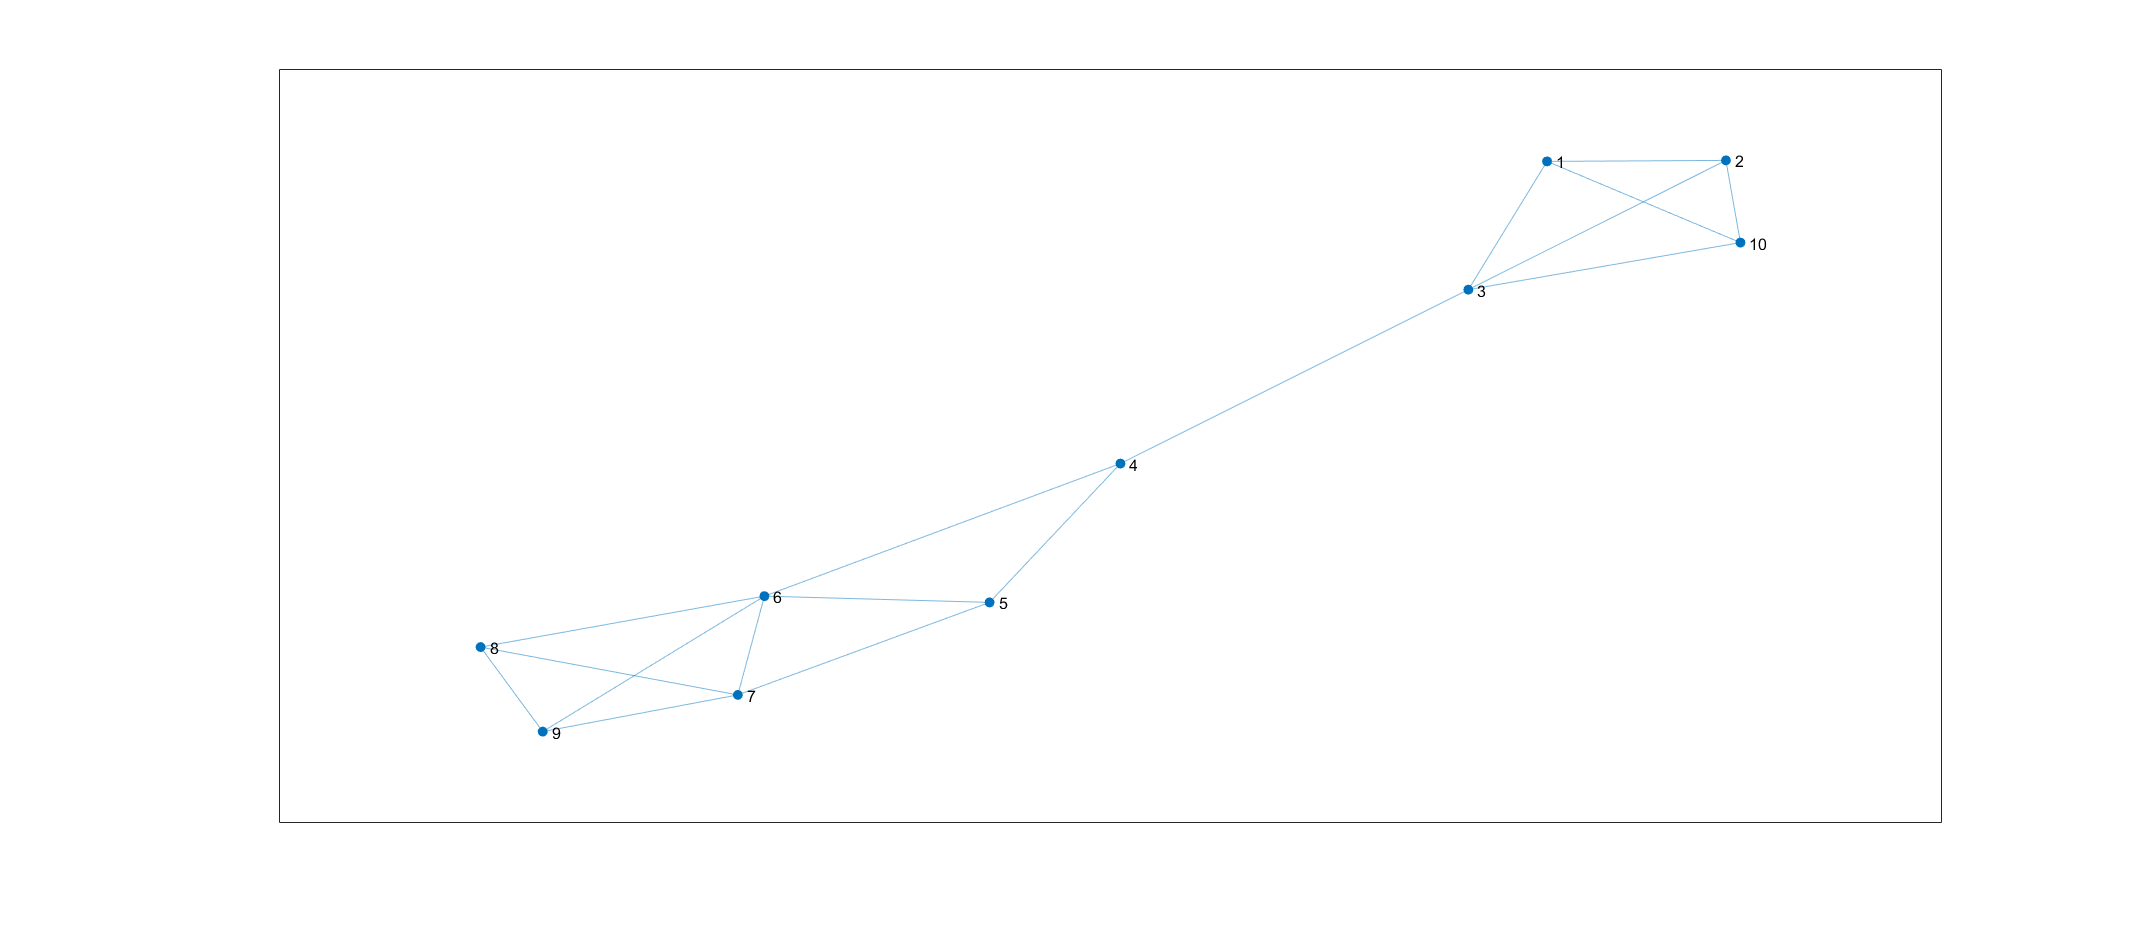

GNN_viz(3,old_adj)

## Designing the Network

We will create a simple classification network with two GCN layers (two accumators) and a fully connected layer. 

GCN = Graph Conv layer (needs weight size as input)

GNN_interface = This layer is needed at the end of GCN layers to provide interface for rest of the network.

Network architecture

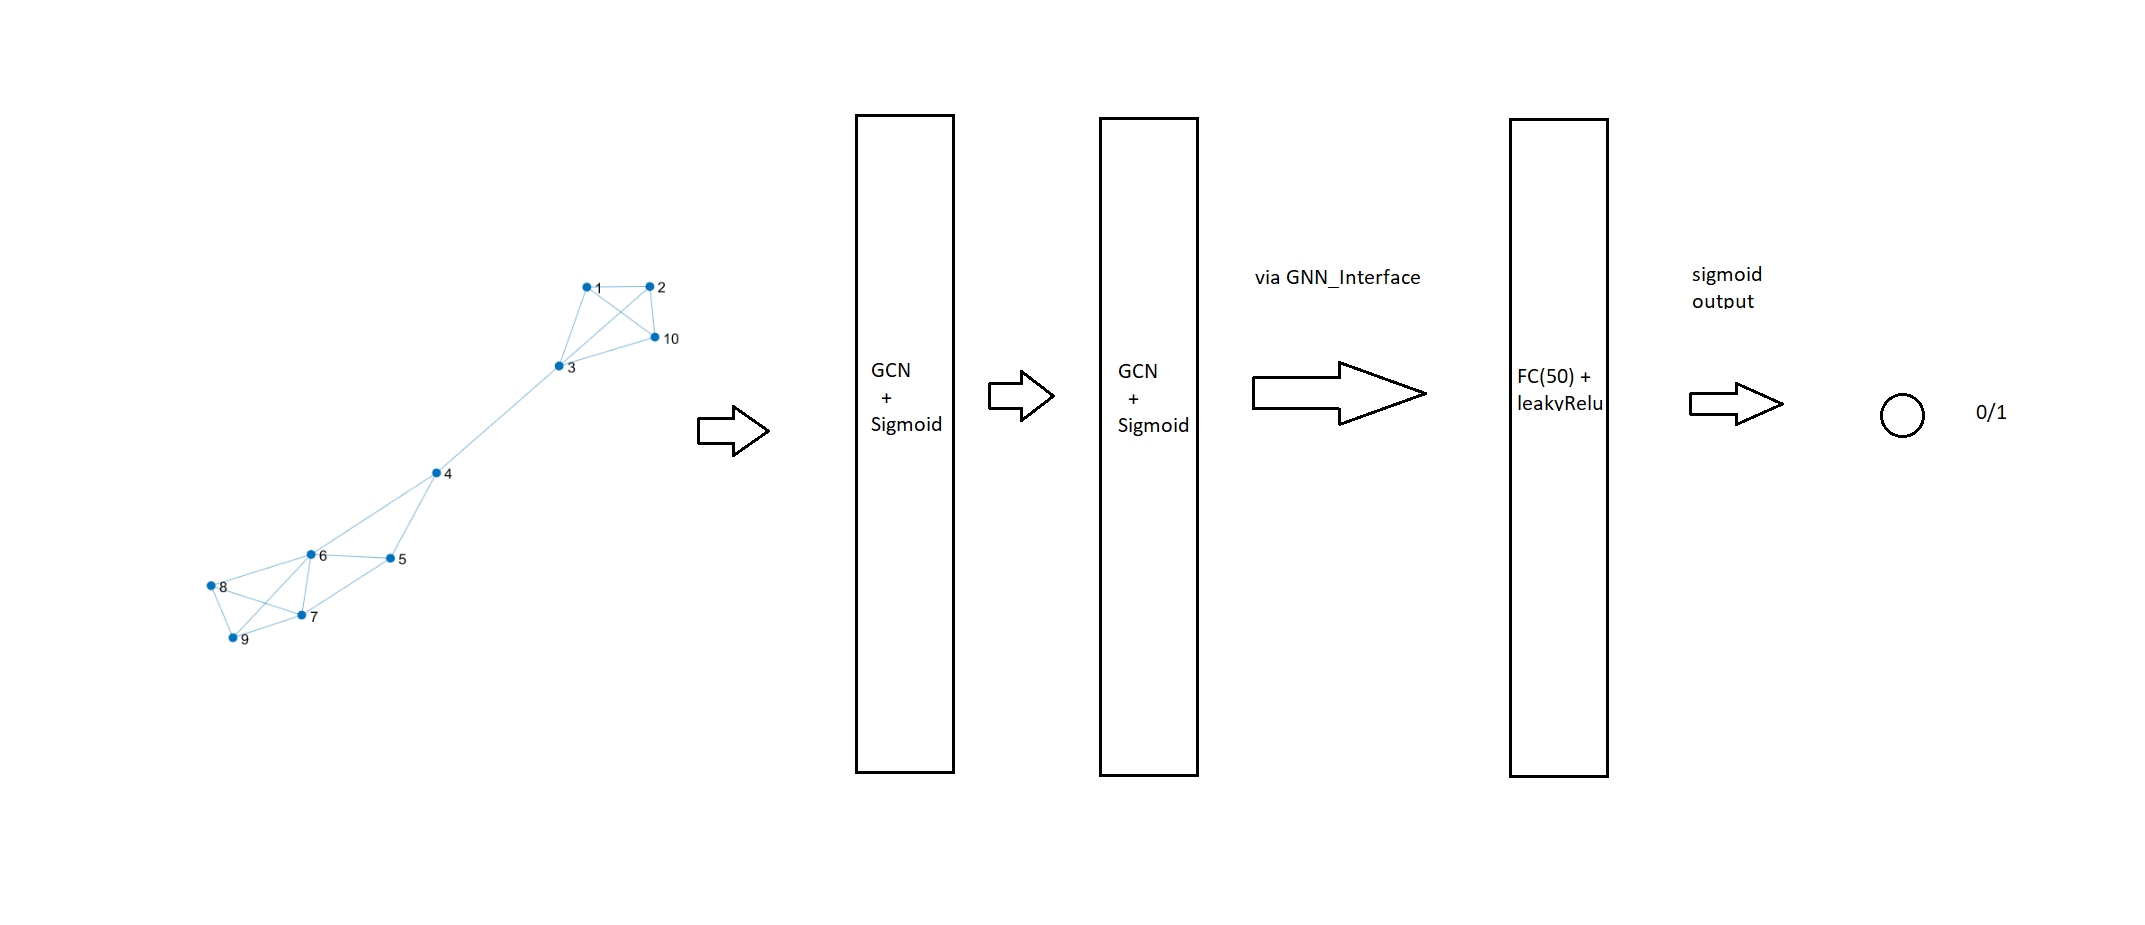

imshow('arch.png')

Input +> GCN -> GCN -> GNN_interface -> FC(30) -> FC(1)

layer4 = fullyConnectedLayer(30,'Name','fc1');
layer5 = fullyConnectedLayer(1,'Name','fc2');
act1 = leakyReluLayer(0.1,'Name','lr');
act2 = sigmoidLayer('Name','ss');
my_net = [layer4,act1,layer5,act2];

Now we connect the layers and create a 'dlnetwork' object

feata = dlarray(ones([50,1]),'C');
lgraph = layerGraph();
lgraph = addLayers(lgraph,my_net);
%create a dlnetwork with sample input
my_net = dlnetwork(lgraph,feata);


Lets plot out our graph

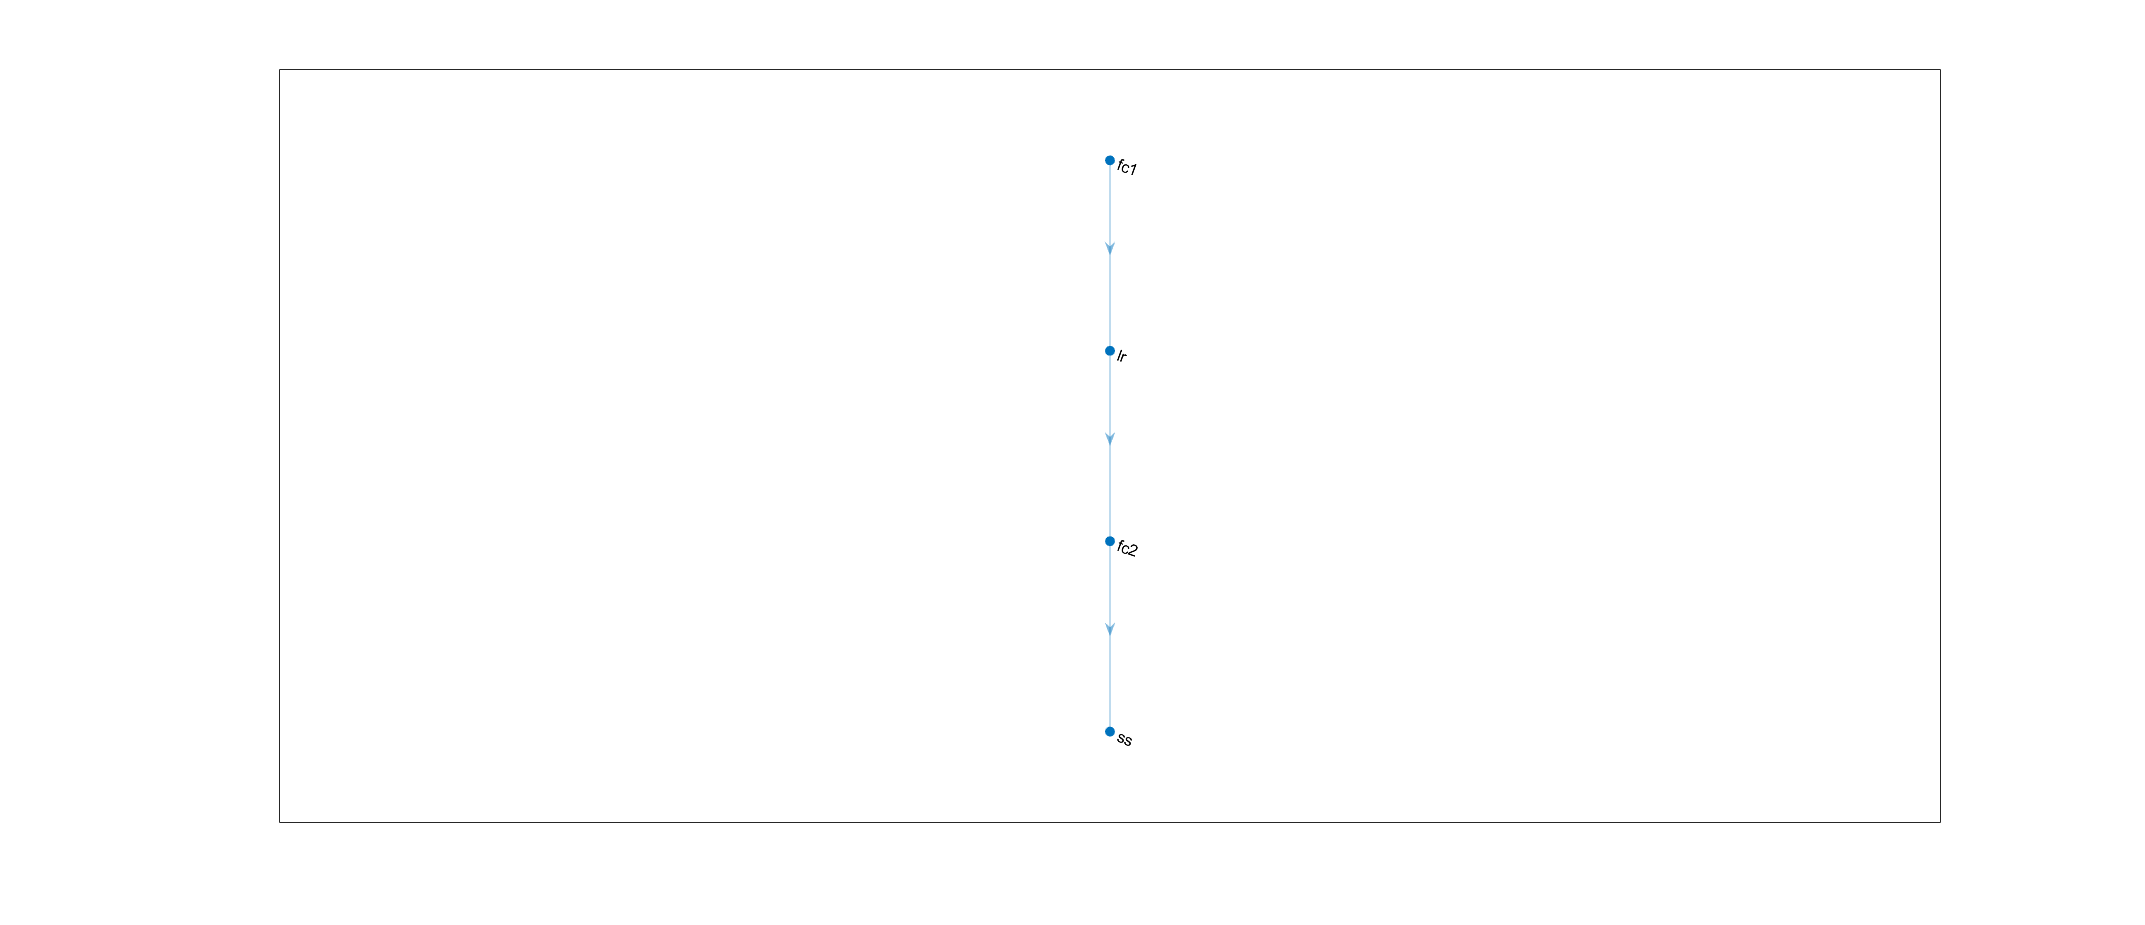

plot(lgraph)

## **Network Training**

We first set the hyperparameters for training out network

train_len = length(shuff)

train_len = 671

epochs = 30;
learnRate = 0.01;
momentum = 0.90;
vel = [];

Let the training begin,

for j=1:epochs
losstot=0;
for i=1:train_len
    var1=dlarray(adj{shuff(i)},'CU');
    var2=dlarray(feat{shuff(i)},'C');
    var3=dlarray(label(shuff(i))-1,'CB');
    [grad,los]=dlfeval(@Gradients,my_net,var2,var3);
    losstot = losstot + los;
    [my_net,vel] = sgdmupdate(my_net,grad,vel,learnRate,momentum);
end   
disp(['Total error for epoch ',num2str(j),' is : ',num2str(losstot)])
end

Total error for epoch 1 is : 433.7002
Total error for epoch 2 is : 403.1862
Total error for epoch 3 is : 397.4742
Total error for epoch 4 is : 394.7048
Total error for epoch 5 is : 390.3013
Total error for epoch 6 is : 388.3994
Total error for epoch 7 is : 382.5097
Total error for epoch 8 is : 379.8725
Total error for epoch 9 is : 374.0591
Total error for epoch 10 is : 373.0906
Total error for epoch 11 is : 369.6221
Total error for epoch 12 is : 362.1757
Total error for epoch 13 is : 359.9046
Total error for epoch 14 is : 353.3213
Total error for epoch 15 is : 349.0021
Total error for epoch 16 is : 343.6274
Total error for epoch 17 is : 341.805
Total error for epoch 18 is : 340.3155
Total error for epoch 19 is : 334.6338
Total error for epoch 20 is : 325.7014
Total error for epoch 21 is : 329.1202
Total error for epoch 22 is : 316.7338
Total error for epoch 23 is : 312.1229
Total error for epoch 24 is : 306.185
Total error for epoch 25 is : 304.1951
Total error for epoch 26 is : 296.89

Finally we test the accuracy of the network on the 101 graphs we set aside for testing

test(my_net,adj,feat,label,test_set)

train_len = 201

ans = 57.7114

**Accuracy of 71-72 is not great! but its not bad either considering SOTA is 84% on PROTEINS** and our network was the most basic one and trained only on a subset of graphs. Some future things that I intend to try to increase the accuracy:

1) Graph Batching: We did not have any batching whatsover.

2) Graph Pooling : Pooling operations would be useful in graph classification tasks.

3) Optimizations and network tuning

4) Add gpuArray support

function [gradients,loss] = Gradients(dlnet,feat,target)

out = forward(dlnet,feat);
loss = crossentropy(out,target,'TargetCategories','independent');
gradients = dlgradient(loss,dlnet.Learnables);

end

function acc = test(dlnet,adj,feat,label,test_idx)
acc = 0;
train_len = length(test_idx)
    for i=1:train_len
    var1=dlarray(adj{test_idx(i)},'CU');
    var2=dlarray(feat{test_idx(i)},'C');
    var3=dlarray(label(test_idx(i))-1,'CB');
    out=round(predict(dlnet,var2));
    if out==var3
        acc = acc +1;
    end
    end  
    acc =acc*100 /length(test_idx);
end